% ========================================================
% === SCRIPT COMPLETO (Versione “pipeline + SVD_BC”) ===
% ========================================================
clear; clc; close all;
rng(0);

%% ----------------------------------------------------------------
%% 0) IMPOSTAZIONE AMBIENTE & CARTELLA RISULTATI
%% ----------------------------------------------------------------

this_folder  = pwd;
results_path = fullfile(this_folder,'results');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% ----------------------------------------------------------------
%% 1) PARAMETRI GLOBALI
%% ----------------------------------------------------------------
epochs       = 40;        
base_lr      = 0.01;      
lambda       = 1e-4;      
dropout_rate = 0.2;       
batch_size   = 32;        
patience     = 5;         

%% ----------------------------------------------------------------
%% 2) CARICAMENTO DATASET ORL
%% ----------------------------------------------------------------
fprintf('>>> Caricamento dataset ORL...\n');

>>> Caricamento dataset ORL...


tic;
load('dataset/volti_dataset.mat');  % A (m×n), labels
A      = double(A)/255;
labels = labels(:);
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.07 s



img_h = 112;
img_w = 92;
[m, n] = size(A);
num_classes = max(labels);

%% ----------------------------------------------------------------
%% 2.1) SVD: volto medio, centratura, SVD con svd_BC
%% ----------------------------------------------------------------
tol   = 1e-4;
maxit = 1000;

fprintf('>>> Calcolo volto medio...\n');  t0 = tic;

>>> Calcolo volto medio...


mean_face = mean(A,2);
save(fullfile(results_path,'mean_face.mat'),'mean_face');
fprintf('   ok in %.2f s\n', toc(t0));

   ok in 0.01 s



fprintf('>>> Centratura dati...\n');  t0 = tic;

>>> Centratura dati...


A_centered = A - mean_face;
fprintf('   ok in %.2f s\n', toc(t0));

   ok in 0.01 s



fprintf('>>> Lancio svd_BC (tol=%.1e,maxit=%d)...\n',tol,maxit);  t0 = tic;

>>> Lancio svd_BC (tol=1.0e-04,maxit=1000)...


[U, S, V] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 410x410 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=410 ... 

iter=1001 time=8.91 s
         [qr_eig] deflazione k=409 ... 

iter=1001 time=9.46 s
         [qr_eig] deflazione k=408 ... 

iter=1001 time=9.10 s
         [qr_eig] deflazione k=407 ... 

iter=1001 time=9.20 s
         [qr_eig] deflazione k=406 ... 

iter=1001 time=9.09 s
         [qr_eig] deflazione k=405 ... 

iter=1001 time=9.17 s
         [qr_eig] deflazione k=404 ... iter=611 time=5.49 s
         [qr_eig] deflazione k=403 ... 

iter=1001 time=9.21 s
         [qr_eig] deflazione k=402 ... 

iter=1001 time=9.01 s
         [qr_eig] deflazione k=401 ... 

iter=1001 time=8.98 s
         [qr_eig] deflazione k=400 ... 

iter=1001 time=8.82 s
         [qr_eig] deflazione k=399 ... 

iter=1001 time=8.97 s
         [qr_eig] deflazione k=398 ... 

iter=1001 time=8.78 s
         [qr_eig] deflazione k=397 ... 

iter=1001 time=8.77 s
         [qr_eig] deflazione k=396 ... 

iter=1001 time=9.22 s
         [qr_eig] deflazione k=395 ... 

iter=1001 time=8.76 s
         [qr_eig] deflazione k=394 ... 

iter=1001 time=8.65 s
         [qr_eig] deflazione k=393 ... 

iter=1001 time=8.87 s
         [qr_eig] deflazione k=392 ... 

iter=1001 time=8.49 s
         [qr_eig] deflazione k=391 ... 

iter=1001 time=8.50 s
         [qr_eig] deflazione k=390 ... 

iter=1001 time=8.45 s
         [qr_eig] deflazione k=389 ... 

iter=1001 time=8.44 s
         [qr_eig] deflazione k=388 ... 

iter=1001 time=8.35 s
         [qr_eig] deflazione k=387 ... 

iter=1001 time=8.34 s
         [qr_eig] deflazione k=386 ... iter=407 time=3.73 s
         [qr_eig] deflazione k=385 ... 

iter=1001 time=8.04 s
         [qr_eig] deflazione k=384 ... 

iter=1001 time=7.95 s
         [qr_eig] deflazione k=383 ... 

iter=1001 time=8.06 s
         [qr_eig] deflazione k=382 ... 

iter=1001 time=8.06 s
         [qr_eig] deflazione k=381 ... 

iter=1001 time=8.22 s
         [qr_eig] deflazione k=380 ... 

iter=1001 time=8.05 s
         [qr_eig] deflazione k=379 ... 

iter=1001 time=8.34 s
         [qr_eig] deflazione k=378 ... iter=136 time=1.16 s
         [qr_eig] deflazione k=377 ... 

iter=1001 time=8.57 s
         [qr_eig] deflazione k=376 ... 

iter=1001 time=7.95 s
         [qr_eig] deflazione k=375 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=374 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=373 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=372 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=371 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=370 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=369 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=368 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=367 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=366 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=365 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=364 ... 

iter=1001 time=7.52 s
         [qr_eig] deflazione k=363 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=362 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=361 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=360 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=359 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=358 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=357 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=356 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=355 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=354 ... iter=478 time=3.43 s
         [qr_eig] deflazione k=353 ... 

iter=1001 time=7.09 s
         [qr_eig] deflazione k=352 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=351 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=350 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=349 ... 

iter=1001 time=7.16 s
         [qr_eig] deflazione k=348 ... 

iter=1001 time=6.99 s
         [qr_eig] deflazione k=347 ... 

iter=1001 time=6.95 s
         [qr_eig] deflazione k=346 ... 

iter=1001 time=7.08 s
         [qr_eig] deflazione k=345 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=344 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=343 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=342 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=341 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=340 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=339 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=338 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=337 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=336 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=335 ... 

iter=1001 time=7.62 s
         [qr_eig] deflazione k=334 ... 

iter=1001 time=6.69 s
         [qr_eig] deflazione k=333 ... iter=39 time=0.31 s
         [qr_eig] deflazione k=332 ... 

iter=1001 time=6.33 s
         [qr_eig] deflazione k=331 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=330 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=329 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=328 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=327 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=326 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=325 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=324 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=323 ... iter=2 time=0.01 s
         [qr_eig] deflazione k=322 ... 

iter=1001 time=6.33 s
         [qr_eig] deflazione k=321 ... 

iter=1001 time=5.93 s
         [qr_eig] deflazione k=320 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=319 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=318 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=317 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=316 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=315 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=314 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=313 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=312 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=311 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=310 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=309 ... 

iter=1001 time=5.81 s
         [qr_eig] deflazione k=308 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=307 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=306 ... iter=170 time=1.34 s
         [qr_eig] deflazione k=305 ... iter=222 time=2.45 s
         [qr_eig] deflazione k=304 ... iter=901 time=9.65 s
         [qr_eig] deflazione k=303 ... 

iter=1001 time=11.12 s
         [qr_eig] deflazione k=302 ... iter=11 time=0.10 s
         [qr_eig] deflazione k=301 ... 

iter=1001 time=10.91 s
         [qr_eig] deflazione k=300 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=299 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=298 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=297 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=296 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=295 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=294 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=293 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=292 ... iter=326 time=3.77 s
         [qr_eig] deflazione k=291 ... 

iter=1001 time=10.27 s
         [qr_eig] deflazione k=290 ... 

iter=1001 time=7.82 s
         [qr_eig] deflazione k=289 ... 

iter=1001 time=5.03 s
         [qr_eig] deflazione k=288 ... 

iter=1001 time=4.93 s
         [qr_eig] deflazione k=287 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=286 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=285 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=284 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=283 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=282 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=281 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=280 ... 

iter=1001 time=4.76 s
         [qr_eig] deflazione k=279 ... 

iter=1001 time=4.79 s
         [qr_eig] deflazione k=278 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=277 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=276 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=275 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=274 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=273 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=272 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=271 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=270 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=269 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=268 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=267 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=266 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=265 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=264 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=263 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=262 ... iter=0 time

iter=1001 time=4.43 s
         [qr_eig] deflazione k=259 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=258 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=257 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=256 ... 

iter=1001 time=4.00 s
         [qr_eig] deflazione k=255 ... iter=2 time=0.01 s
         [qr_eig] deflazione k=254 ... 

iter=1001 time=3.95 s
         [qr_eig] deflazione k=253 ... iter=312 time=1.31 s
         [qr_eig] deflazione k=252 ... iter=626 time=2.53 s
         [qr_eig] deflazione k=251 ... 

iter=1001 time=3.93 s
         [qr_eig] deflazione k=250 ... 

iter=1001 time=3.96 s
         [qr_eig] deflazione k=249 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=248 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=247 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=246 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=245 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=244 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=243 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=242 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=241 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=240 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=239 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=238 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=237 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=236 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=235 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=234 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=233 ... 

iter=1001 time=3.72 s
         [qr_eig] deflazione k=232 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=231 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=230 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=229 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=228 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=227 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=226 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=225 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=224 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=223 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=222 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=221 ... 

iter=1001 time=3.13 s
         [qr_eig] deflazione k=220 ... 

iter=1001 time=3.08 s
         [qr_eig] deflazione k=219 ... 

iter=1001 time=3.08 s
         [qr_eig] deflazione k=218 ... 

iter=1001 time=3.03 s
         [qr_eig] deflazione k=217 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=216 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=215 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=214 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=213 ... iter=561 time=1.89 s
         [qr_eig] deflazione k=212 ... 

iter=1001 time=2.98 s
         [qr_eig] deflazione k=211 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=210 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=209 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=208 ... 

iter=1001 time=2.77 s
         [qr_eig] deflazione k=207 ... 

iter=1001 time=2.72 s
         [qr_eig] deflazione k=206 ... 

iter=1001 time=2.77 s
         [qr_eig] deflazione k=205 ... 

iter=1001 time=2.63 s
         [qr_eig] deflazione k=204 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=203 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=202 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=201 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=200 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=199 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=198 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=197 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=196 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=195 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=194 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=193 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=192 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=191 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=190 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=189 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=188 ... iter=0 time

iter=1001 time=2.18 s
         [qr_eig] deflazione k=173 ... iter=760 time=1.74 s
         [qr_eig] deflazione k=172 ... 

iter=1001 time=2.54 s
         [qr_eig] deflazione k=171 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=170 ... 

iter=1001 time=2.02 s
         [qr_eig] deflazione k=169 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=168 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=167 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=166 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=165 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=164 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=163 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=162 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=161 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=160 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=159 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=158 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=157 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=156 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=155 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=154 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=153 ... iter=0 time

iter=1001 time=0.25 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... 

iter=1001 time=0.20 s
         [qr_eig] deflazione k=48 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=47 ... iter=3 time=0.00 s
         [qr_eig] deflazione k=46 ... iter=35 time=0.01 s
         [qr_eig] deflazione k=45 ... 

iter=1001 time=0.17 s
         [qr_eig] deflazione k=44 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=43 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=42 ... 

iter=1001 time=0.15 s
         [qr_eig] deflazione k=41 ... iter=1 time=0.00 s
         [qr_eig] deflazione k=40 ... 

iter=1001 time=0.14 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=29 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=28 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=27 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=26 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=25 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=24 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=23 ... iter=0 time=0.00 s
         

iter=1001 time=0.02 s
         [qr_eig] deflazione k=9 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=8 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=7 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=6 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=5 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=4 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=3 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=2 ... iter=0 time=0.00 s
      [qr_eig] tutti autovalori estratti.
   [svd_BC] qr_eig completata in 515.47 s
   [svd_BC] costruisco S e U...


fprintf('   completata in %.2f s\n', toc(t0));

   completata in 515.81 s


save(fullfile(results_path,'svd_data.mat'),'U','S','V');

%% ----------------------------------------------------------------
%% 2.2) Visualizzazione mean face + prime 9 eigenfaces
%% ----------------------------------------------------------------
fprintf('>>> Visualizzo e salvo immagini SVD...\n');

>>> Visualizzo e salvo immagini SVD...


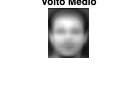

figure('Name','Volto Medio','NumberTitle','off');
imshow(reshape(mean_face,112,92),[]);
title('Volto Medio');
saveas(gcf,fullfile(results_path,'volto_medio.png'));

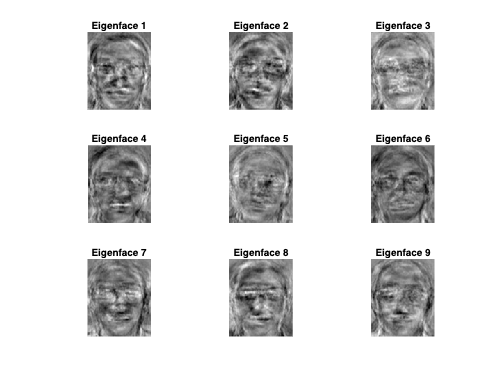


figure('Name','Prime 9 Eigenfaces','NumberTitle','off');
for i = 1:9
    subplot(3,3,i);
    imshow(reshape(U(:,i),112,92),[]);
    title(sprintf('Eigenface %d',i));
end
saveas(gcf,fullfile(results_path,'prime9_eigenfaces.png'));


%% ----------------------------------------------------------------
%% 3) PREPARAZIONE IMMAGINI (reshape) E SPLIT 5 vs 5
%% ----------------------------------------------------------------
k = 300

k = 300


A_rec = U(:,1:k)*S(1:k,1:k)*V(:,1:k)' + mean_face;
imgs   = reshape(A_rec, img_h, img_w, []);

train_idx = [];  test_idx = [];
for s = 1:num_classes
    idx_s = find(labels==s);
    idx_s = idx_s(randperm(length(idx_s)));
    train_idx = [train_idx; idx_s(1:5)];
    test_idx  = [test_idx;  idx_s(6:end)];
end
imgs_train_base = imgs(:,:,train_idx);
y_train_base    = labels(train_idx)';
imgs_test       = imgs(:,:,test_idx);
y_test          = labels(test_idx)';

%% ----------------------------------------
%% 4) DATA AUGMENTATION SU TRAIN BASE (×12)
%% ----------------------------------------
[H, W, N_base] = size(imgs_train_base);  % 112×92×200
aug_per_image  = 12;                     % 1 originale + 11 augment
N_aug          = N_base * aug_per_image; % 200 × 12 = 2400

imgs_train_aug = zeros(H, W, N_aug);
y_train_aug    = zeros(1, N_aug);
cnt = 0;

for i = 1:N_base
    x   = imgs_train_base(:, :, i);    % [112×92]
    lbl = y_train_base(i);

    % 1) Originale
    cnt = cnt + 1;
    imgs_train_aug(:, :, cnt) = x;
    y_train_aug(cnt) = lbl;

    % 2) Traslazioni ±2 orizzontali, ±1 verticali (4)
    x_sh1 = imtranslate(x, [2, 0], 'FillValues', 0);
    x_sh2 = imtranslate(x, [-2, 0], 'FillValues', 0);
    x_sh3 = imtranslate(x, [0, 1], 'FillValues', 0);
    x_sh4 = imtranslate(x, [0, -1], 'FillValues', 0);
    for xx = {x_sh1, x_sh2, x_sh3, x_sh4}
        cnt = cnt + 1;
        imgs_train_aug(:, :, cnt) = xx{1};
        y_train_aug(cnt) = lbl;
    end

    % 3) Rotazioni ±5°, ±10° (4)
    x_r5p  = imrotate(x,  5, 'bilinear', 'crop');
    x_r5n  = imrotate(x, -5, 'bilinear', 'crop');
    x_r10p = imrotate(x, 10, 'bilinear', 'crop');
    x_r10n = imrotate(x, -10,'bilinear', 'crop');
    for xx = {x_r5p, x_r5n, x_r10p, x_r10n}
        cnt = cnt + 1;
        imgs_train_aug(:, :, cnt) = xx{1};
        y_train_aug(cnt) = lbl;
    end

    % 4) Zoom in +10%, Zoom out −10% (2)
    tmp_in  = imresize(x, 1.10);   x_zi = imresize(tmp_in, [H, W]);
    tmp_out = imresize(x, 0.90);   x_zo = imresize(tmp_out, [H, W]);
    for xx = {x_zi, x_zo}
        cnt = cnt + 1;
        imgs_train_aug(:, :, cnt) = xx{1};
        y_train_aug(cnt) = lbl;
    end

    % 5) Flip orizzontale (1)
    x_f = fliplr(x);
    cnt = cnt + 1;
    imgs_train_aug(:, :, cnt) = x_f;
    y_train_aug(cnt) = lbl;
end

assert(cnt == N_aug, 'Errore: il numero di esempi augmentato non corrisponde.');

%% --------------------------------------------------------
%% 5) CREAZIONE DEL VALIDATION SET (20% DI TRAIN AUMENTATO)
%% --------------------------------------------------------
perm_aug   = randperm(N_aug);
val_count  = round(0.20 * N_aug);          
val_idx_aug   = perm_aug(1:val_count);        % 480 (20% di 2400)
train_idx_aug = perm_aug(val_count+1:end);    % 1920 (80% di 2400)

imgs_train_eff = imgs_train_aug(:, :, train_idx_aug);   % [112×92×1920]
y_train_eff    = y_train_aug(train_idx_aug);            % [1×1920]
imgs_val       = imgs_train_aug(:, :, val_idx_aug);     % [112×92×480]
y_val          = y_train_aug(val_idx_aug);              % [1×480]

% One-hot per train e validation
Y_train_eff = zeros(num_classes, numel(y_train_eff));
for j = 1:numel(y_train_eff)
    Y_train_eff(y_train_eff(j), j) = 1;
end
Y_val = zeros(num_classes, numel(y_val));
for j = 1:numel(y_val)
    Y_val(y_val(j), j) = 1;
end

%% ---------------------------------------
%% 6) DEFINIZIONE ARCHITETTURA DELLA CNN
%% ---------------------------------------
% Rete con 3 layer conv + pool, poi fully-connected
f1 = 3;  n_f1 = 8;    % primo layer conv 3×3×8
f2 = 3;  n_f2 = 16;   % secondo layer conv 3×3×16
f3 = 3;  n_f3 = 8;    % terzo layer conv 3×3×8
pool = 2;

% Calcolo dimensioni feature map progressivamente:
conv1_h = img_h - f1 + 1;   % 110
conv1_w = img_w - f1 + 1;   % 90
pool1_h = floor(conv1_h / pool);  % 55
pool1_w = floor(conv1_w / pool);  % 45

conv2_h = pool1_h - f2 + 1; % 53
conv2_w = pool1_w - f2 + 1; % 43
pool2_h = floor(conv2_h / pool);  % 26
pool2_w = floor(conv2_w / pool);  % 21

conv3_h = pool2_h - f3 + 1; % 24
conv3_w = pool2_w - f3 + 1; % 19
pool3_h = floor(conv3_h / pool);  % 12
pool3_w = floor(conv3_w / pool);  % 9

% Dimensione finale del flatten:
fc_input_size = pool3_h * pool3_w * n_f3;  % 12×9×8 = 864
fprintf('[DEBUG arch] fc_input_size (layer 3) = %d\n', fc_input_size);

[DEBUG arch] fc_input_size (layer 3) = 864



% -------------------------------
% Inizializzazione pesi (He per conv, FC)
% -------------------------------
rng(0);
filters1 = randn(f1, f1, n_f1) * sqrt(2/(f1*f1*n_f1));   bias1 = zeros(n_f1, 1);
filters2 = randn(f2, f2, n_f2, n_f1) * sqrt(2/(f2*f2*n_f2)); bias2 = zeros(n_f2, 1);
filters3 = randn(f3, f3, n_f3, n_f2) * sqrt(2/(f3*f3*n_f3)); bias3 = zeros(n_f3, 1);

W_fc = randn(num_classes, fc_input_size) * sqrt(2 / fc_input_size);
b_fc = zeros(num_classes, 1);

%% ----------------------------------------------------
%% 7) TRAINING CON MINI‐BATCH, LR SCHEDULING,
%%    DROPOUT, L2, EARLY STOPPING SU VALIDATION
%% ----------------------------------------------------
loss_history   = zeros(1, epochs);
acc_history    = zeros(1, epochs);
val_loss_hist  = zeros(1, epochs);
val_acc_hist   = zeros(1, epochs);

best_val_acc       = 0;
best_params        = struct();
no_improve_counter = 0;

num_train_eff = size(imgs_train_eff, 3);
num_batches    = floor(num_train_eff / batch_size);

for epoch = 1:epochs
    % Aggiorno learning rate (decay a epocha 26)
    if epoch == 26
        lr = base_lr * 0.1;
    else
        lr = base_lr;
    end

    % Shuffle mini‐batch
    perm = randperm(num_train_eff);
    total_loss = 0;
    correct    = 0;

    for b = 1:num_batches
        idx_b = perm((b-1)*batch_size + (1:batch_size));
        Xb = imgs_train_eff(:, :, idx_b);    % [112×92×32]
        Yb = Y_train_eff(:, idx_b);          % [40×32]
        Nb = size(Xb, 3);

        % Inizializzo gradienti accumulati su batch
        dW1  = zeros(size(filters1)); db1  = zeros(size(bias1));
        dW2  = zeros(size(filters2)); db2  = zeros(size(bias2));
        dW3  = zeros(size(filters3)); db3  = zeros(size(bias3));
        dWfc = zeros(size(W_fc));      dbfc = zeros(size(b_fc));

        % ===================
        % === FORWARD BATCH ==
        % ===================
        for i_b = 1:Nb
            x      = Xb(:, :, i_b);
            y_true = Yb(:, i_b);

            % -- conv1 + ReLU + pool1 --
            [c1, cache1] = conv2d_forward(x, filters1, bias1);
            r1 = max(c1, 0);  % ReLU
            [p1, mask1] = maxpool2d_forward(r1, pool);

            % -- conv2 + ReLU + pool2 --
            [c2, cache2] = conv2d_forward_multi(p1, filters2, bias2);
            r2 = max(c2, 0);
            [p2, mask2] = maxpool2d_forward(r2, pool);

            % -- conv3 + ReLU + pool3 --
            [c3, cache3] = conv2d_forward_multi(p2, filters3, bias3);
            r3 = max(c3, 0);
            [p3, mask3] = maxpool2d_forward(r3, pool);

            % -- flatten e dropout --
            x_fc = reshape(p3, [], 1);           % [864×1]
            dropout_mask = (rand(size(x_fc)) > dropout_rate);
            x_fc_do = x_fc .* dropout_mask / (1 - dropout_rate);

            % -- fully‐connected + softmax --
            z_fc = W_fc * x_fc_do + b_fc;        % [40×1]
            z_fc = z_fc - max(z_fc);
            expz = exp(z_fc);
            y_pred = expz / sum(expz);

            % -- loss & accuracy --
            loss = -sum(y_true .* log(y_pred + 1e-12));
            total_loss = total_loss + loss;
            [~, pl] = max(y_pred); [~, tl] = max(y_true);
            if pl == tl
                correct = correct + 1;
            end

            % ======================
            % === BACKWARD BATCH ===
            % ======================
            dz_fc    = y_pred - y_true;             % [40×1]
            dWfc_b   = dz_fc * x_fc_do';            % [40×864]
            dbfc_b   = dz_fc;                       % [40×1]

            dx_fc_do = W_fc' * dz_fc;               % [864×1]
            dx_fc    = dx_fc_do .* dropout_mask / (1 - dropout_rate);

            dp3 = reshape(dx_fc, size(p3));         % [12×9×8]
            dr3 = maxpool2d_backward(dp3, mask3);   % Usa pool_h=floor(H/H_p), pool_w=floor(W/W_p)
            dc3 = dr3 .* (c3 > 0);
            [dp2, dW3_b, db3_b] = conv2d_backward_multi(p2, filters3, dc3, cache3);

            dr2 = maxpool2d_backward(dp2, mask2);
            dc2 = dr2 .* (c2 > 0);
            [dp1, dW2_b, db2_b] = conv2d_backward_multi(p1, filters2, dc2, cache2);

            dr1 = maxpool2d_backward(dp1, mask1);
            dc1 = dr1 .* (c1 > 0);
            [~, dW1_b, db1_b] = conv2d_backward(x, filters1, dc1, cache1);

            % Accumulo gradienti sul batch
            dWfc = dWfc + dWfc_b;   dbfc = dbfc + dbfc_b;
            dW3  = dW3  + dW3_b;    db3  = db3  + db3_b;
            dW2  = dW2  + dW2_b;    db2  = db2  + db2_b;
            dW1  = dW1  + dW1_b;    db1  = db1  + db1_b;
        end  % fine i_b su Nb

        % ============================
        % === UPDATE PESI (batch) ====
        % ============================
        filters1 = filters1 - lr * (dW1 / Nb + lambda * filters1);
        bias1    = bias1    - lr * (db1 / Nb);
        filters2 = filters2 - lr * (dW2 / Nb + lambda * filters2);
        bias2    = bias2    - lr * (db2 / Nb);
        filters3 = filters3 - lr * (dW3 / Nb + lambda * filters3);
        bias3    = bias3    - lr * (db3 / Nb);

        W_fc = W_fc - lr * (dWfc / Nb + lambda * W_fc);
        b_fc = b_fc - lr * (dbfc / Nb);
    end  % fine loop batches

    % ===============================
    % === CALCOLO STATISTICHE E STOPOGGING ===
    % ===============================
    loss_history(epoch) = total_loss / num_train_eff;
    acc_history(epoch)  = correct / num_train_eff * 100;

    % --- VALIDATION (solo forward) ---
    correct_val = 0;
    val_loss = 0;
    N_val = numel(y_val);

    for j = 1:N_val
        x      = imgs_val(:, :, j);
        y_true = Y_val(:, j);

        [c1, ~] = conv2d_forward(x, filters1, bias1); r1 = max(c1, 0);
        [p1, ~] = maxpool2d_forward(r1, pool);
        [c2, ~] = conv2d_forward_multi(p1, filters2, bias2); r2 = max(c2, 0);
        [p2, ~] = maxpool2d_forward(r2, pool);
        [c3, ~] = conv2d_forward_multi(p2, filters3, bias3); r3 = max(c3, 0);
        [p3, ~] = maxpool2d_forward(r3, pool);

        x_fc = reshape(p3, [], 1);
        z_fc = W_fc * x_fc + b_fc;
        z_fc = z_fc - max(z_fc);
        expz = exp(z_fc);
        y_pred = expz / sum(expz);

        loss_v = -sum(y_true .* log(y_pred + 1e-12));
        val_loss = val_loss + loss_v;
        [~, pl] = max(y_pred); [~, tl] = max(y_true);
        if pl == tl
            correct_val = correct_val + 1;
        end
    end

    val_loss_hist(epoch) = val_loss / N_val;
    val_acc_hist(epoch)  = correct_val / N_val * 100;

    fprintf('[EPOCA %2d] Train Loss=%.4f Acc=%.2f%% | Val Loss=%.4f Acc=%.2f%%\n', ...
            epoch, loss_history(epoch), acc_history(epoch), val_loss_hist(epoch), val_acc_hist(epoch));

    % Early stopping: se validazione non migliora per 'patience' epoche
    if val_acc_hist(epoch) > best_val_acc
        best_val_acc = val_acc_hist(epoch);
        best_params.filters1 = filters1;
        best_params.bias1    = bias1;
        best_params.filters2 = filters2;
        best_params.bias2    = bias2;
        best_params.filters3 = filters3;
        best_params.bias3    = bias3;
        best_params.W_fc     = W_fc;
        best_params.b_fc     = b_fc;
        best_params.pool     = pool;
        no_improve_counter   = 0;
    else
        no_improve_counter = no_improve_counter + 1;
        if no_improve_counter >= patience
            fprintf('Early stopping: non migliora validazione da %d epoche!\n', patience);
            break;
        end
    end
end  % fine epoche

[EPOCA  1] Train Loss=3.6952 Acc=1.73% | Val Loss=3.7187 Acc=1.02%
[EPOCA  2] Train Loss=3.6822 Acc=2.95% | Val Loss=3.7125 Acc=2.64%
[EPOCA  3] Train Loss=3.6794 Acc=3.15% | Val Loss=3.7095 Acc=2.44%
[EPOCA  4] Train Loss=3.6742 Acc=3.25% | Val Loss=3.7058 Acc=3.86%
[EPOCA  5] Train Loss=3.6715 Acc=4.01% | Val Loss=3.7015 Acc=4.27%
[EPOCA  6] Train Loss=3.6631 Acc=4.93% | Val Loss=3.7012 Acc=5.49%
[EPOCA  7] Train Loss=3.6587 Acc=5.28% | Val Loss=3.6907 Acc=4.47%
[EPOCA  8] Train Loss=3.6521 Acc=5.08% | Val Loss=3.6826 Acc=5.89%
[EPOCA  9] Train Loss=3.6375 Acc=7.06% | Val Loss=3.6720 Acc=5.89%
[EPOCA 10] Train Loss=3.6229 Acc=6.55% | Val Loss=3.6611 Acc=7.11%
[EPOCA 11] Train Loss=3.6050 Acc=8.08% | Val Loss=3.6312 Acc=8.13%
[EPOCA 12] Train Loss=3.5691 Acc=10.32% | Val Loss=3.6055 Acc=9.15%
[EPOCA 13] Train Loss=3.5203 Acc=11.89% | Val Loss=3.5277 Acc=15.65%
[EPOCA 14] Train Loss=3.4256 Acc=15.45% | Val Loss=3.3838 Acc=22.15%
[EPOCA 15] Train Loss=3.2365 Acc=21.34% | Val Loss=3.1046


% Se ci siamo fermati prima di 'epochs', aggiorno epoch effettive:
actual_epochs = epoch;

%% ----------------------------
%% 8) VALUTAZIONE SUL TEST SET
%% ----------------------------
fprintf('>>> Valutazione modello su TEST SET...\n');

>>> Valutazione modello su TEST SET...


filters1 = best_params.filters1; bias1 = best_params.bias1;
filters2 = best_params.filters2; bias2 = best_params.bias2;
filters3 = best_params.filters3; bias3 = best_params.bias3;
W_fc     = best_params.W_fc;     b_fc = best_params.b_fc;
pool     = best_params.pool;

correct_test = 0;
num_test = size(imgs_test, 3);

for i = 1:num_test
    x = imgs_test(:, :, i);

    [c1, ~] = conv2d_forward(x, filters1, bias1);  r1 = max(c1, 0);
    [p1, ~] = maxpool2d_forward(r1, pool);
    [c2, ~] = conv2d_forward_multi(p1, filters2, bias2); r2 = max(c2, 0);
    [p2, ~] = maxpool2d_forward(r2, pool);
    [c3, ~] = conv2d_forward_multi(p2, filters3, bias3); r3 = max(c3, 0);
    [p3, ~] = maxpool2d_forward(r3, pool);

    x_fc = reshape(p3, [], 1);
    z_fc = W_fc * x_fc + b_fc;
    z_fc = z_fc - max(z_fc);
    expz = exp(z_fc);
    y_pred = expz / sum(expz);

    [~, pl] = max(y_pred);
    if pl == y_test(i)
        correct_test = correct_test + 1;
    end
end

acc_test = correct_test / num_test * 100;
fprintf('Accuracy finale sul TEST SET: %.2f%%\n', acc_test);

Accuracy finale sul TEST SET: 69.76%


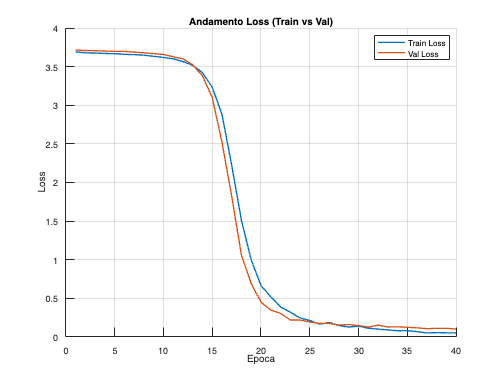


%% ------------------------------
%% 9) PLOTTAGGIO STATISTICHE
%% ------------------------------
figure; hold on;
plot(1:actual_epochs, loss_history(1:actual_epochs), 'LineWidth', 1.5);
plot(1:actual_epochs, val_loss_hist(1:actual_epochs), 'LineWidth', 1.5);
xlabel('Epoca'); ylabel('Loss');
legend('Train Loss', 'Val Loss');
title('Andamento Loss (Train vs Val)');
grid on;

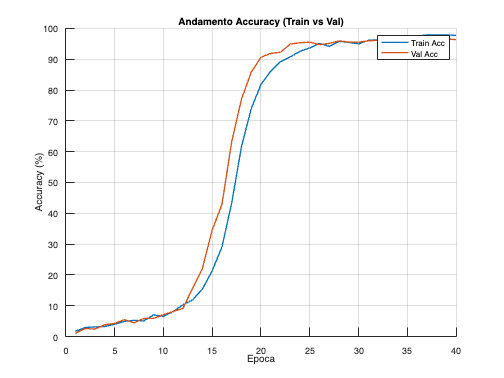


figure; hold on;
plot(1:actual_epochs, acc_history(1:actual_epochs), 'LineWidth', 1.5);
plot(1:actual_epochs, val_acc_hist(1:actual_epochs), 'LineWidth', 1.5);
xlabel('Epoca'); ylabel('Accuracy (%)');
legend('Train Acc', 'Val Acc');
title('Andamento Accuracy (Train vs Val)');
grid on;



%% =============================================================================
%% === 10) OVERRIDE DI maxpool2d_backward (senza toccare il file esterno) ===
 %% =============================================================================
